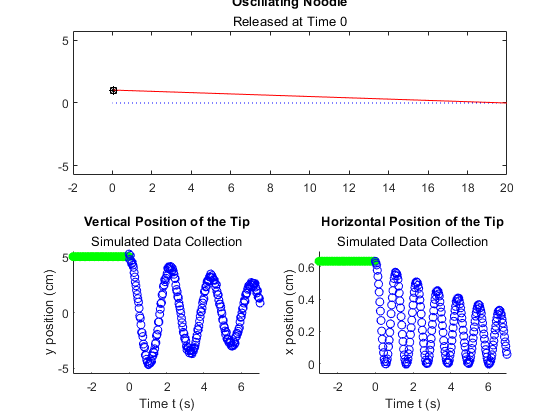

fps = 1/30; % Time per frame, default 30 fps
Dh = 5;     % Initial vertical displacement, default 5 (cm)
L = 20;     % Lenth of beam, default 20 (cm)
tend = 7;   % Time to oscillate, default 7 (s)
tneg = 3;   % Time to release, default 1 (s) 

x0 = sqrt(L^2-Dh^2);
tau = .1;              % Time constant
omega = 1/2.2;         % Oscillatory frequency
t = 0:fps:tend;
negTimes = -tneg:fps:0;
x =  (L-x0)/2*exp(-tau*t).*(cos(4*pi*t*omega)+1);
y = Dh*exp(-tau*t).*cos(2*pi*t*omega);
yData = Dh*exp(-tau*t).*cos(2*pi*t*omega) + .5*(rand(size(t))-.5);
xData = (L-x0)/2*exp(-tau*t).*(cos(4*pi*t*omega)+1) + .01*(rand(size(t))-.5);
rodX = [x; L*ones(size(x))];
rodY = [y; zeros(size(y))];
for k = 1:length(t)
    if k==1
        subplot(2,2,[1,2])
        plot(rodX(:,1), rodY(:,1),"r-")
        title("Oscillating Noodle", "Released at Time 0")
        hold on
        xlim([-L/10, L]);
        ylim([-1.1*max(abs(yData)), 1.1*max(abs(yData))]);
        plot([0, 20], [0, 0], "b:")
        plot([-L/10, x(1)], [y(1), y(1)], "m-", "LineWidth",3)
        hold off
        pause(tneg)
        for j = 1:length(negTimes)
            subplot(2,2,3)
                scatter(negTimes(j), y(1), "go")
                hold on
                xlim([-tneg,tend])
                ylim(([-1.1*Dh, 1.1*Dh]))
                title("Vertical Position of the Tip", "Simulated Data Collection")
                xlabel("Time t (s)")
                ylabel("y position (cm)")
            subplot(2,2,4)
                scatter(negTimes(j), x(1), "go")
                xlim([-tneg, tend])
                ylim([-.1*(L-x0), 1.1*(L-x0)])
                title("Horizontal Position of the Tip", "Simulated Data Collection")
                xlabel("Time t (s)")
                ylabel("x position (cm)")
                hold on
            pause(fps)
        end
    end
subplot(2,2,3)
    scatter(t(k),yData(k), "bo")
subplot(2,2,4)
    scatter(t(k),xData(k), "bo")
subplot(2,2,[1,2])
    plot(rodX(:,k), rodY(:,k),"r-")
    title("Oscillating Noodle", "Released at Time 0")
    xlim([-L/10, L]);
    ylim([-1.1*max(abs(yData)), 1.1*max(abs(yData))]);
    hold on
        plot([0, 20], [0, 0], "b:")
        scatter(x(k), y(k), "k*")
    hold off
    pause(fps)
end
subplot(2,2,[1,2])
hold on
plot(rodX(:,end), rodY(:,end), "r-")
scatter(x(end), y(end), "ks")
hold off
subplot(2,2,3)
hold off
subplot(2,2,4)
hold off